# One-step FAVAR

Tutorial file for testing one-step FAVAR estimators

## Housekeeping

clear
close all
clear classes

rehash path

!!! Setting up pathes, please change the first two lines to fit your file structure!!!


bearpath = fullfile("C:","Git","OGR","BEARX-Toolbox","tbx");
tutpath = fullfile("C:","Git","OGR","BEARX-tutorials");


cd(fullfile(bearpath,"bearing"))
activePackage = "factorOnestep";  
import([activePackage + ".*"])  

addpath(fullfile(bearpath,"bear"))


## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

numPresampled = 100;

## Prepare data and a reduced-form model

Note that the meta information is common to all one-factor FAVAR models, regardless of the specific estimator used.

The properties specific to the one-step FAVAR are as follows:

**reducibleNames** – variables used for constructing the factors. 

**numFactors** – defines how many factors to use

**Important note: **having more blocks ot using the **"slowfast"** method are not allowed for one-step estimation. Therefore only one block is created which is named automatically to **"main"**.

inputTbx = tablex.fromCsv(fullfile(tutpath,"FAVAR.csv"));

estimStart = datex.m(1960,3);
estimEnd = datex.m(2001,8);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["FYFF"],...
    exogenous=[],...
    order=13, ...
    intercept=false, ...
    estimationSpan=estimSpan, ...
    reducibleNames=["IPP" , "IPF" , "IPC" , "IPCD" , "IPCN" , "IPE" , "IPI" , "IPM" , "IPMD" , "IPMND" ,...
        "IPMFG" , "IPD" , "IPN" , "IPMIN" , "IPUT" , "IP" , "IPXMCA" , "PMI" , "PMP" , "GMPYQ" , "GMYXPQ" , ...
        "LHEL" , "LHELX" , "LHEM" , "LHNAG" , "LHUR" , "LHU680" , "LHU5" , "LHU14" , "LHU15" , "LHU26" ,...
        "LPNAG" , "LP" , "LPGD" , "LPMI" , "LPCC" , "LPEM" , "LPED" , "LPEN" , "LPSP" , "LPTU" , "LPT" ,...
        "LPFR" , "LPS" , "LPGOV" , "LPHRM" , "LPMOSA" , "PMEMP" , "GMCQ" , "GMCDQ" , "GMCNQ" , "GMCSQ" ,...
        "GMCANQ" , "HSFR" , "HSNE" , "HSMW" , "HSSOU" , "HSWST" , "HSBR" , "HMOB" , "PMNV" , "PMNO" , ...
        "PMDEL" , "MOCMQ" , "MSONDQ" , "FSNCOM" , "FSPCOM" , "FSPIN" , "FSPCAP" , "FSPUT" , "FSDXP" , ...
        "FSPXE" , "EXRSW" , "EXRJAN" , "EXRUK" , "EXRCAN" , "FYGM3" , "FYGM6" , "FYGT1" , "FYGT5" , ...
        "FYGT10" , "FYAAAC" , "FYBAAC" , "SFYGM3" , "SFYGM6" , "SFYGT1" , "SFYGT5" , "SFYGT10" , ...
        "SFYAAAC" , "SFYBAAC" , "FM1" , "FM2" , "FM3" , "FM2DQ" , "FMFBA" , "FMRRA" , "FMRNBA" , ...
        "FCLNQ" , "FCLBMC" , "CCINRV" , "PMCP" , "PWFSA" , "PWFCSA" , "PWIMSA" , "PWCMSA" , "PSM99Q" , ...
        "PUNEW" , "PU83" , "PU84" , "PU85" , "PUC" , "PUCD" , "PUS" , "PUXF" , "PUXHS" , "PUXM" , "LEHCC" , "LEHM" , "HHSNTN"], ...   
    numFactors = 2, ...
    identificationHorizon=12);
dataH = DataHolder(meta, inputTbx);


## Reduced form models

The estimator-specific settings are always the same as those for the corresponding plain BVARs. Also there are some common settings for all the one-step estimations. these are

**LoadingVariance ** – prior variance for the factor loadings

**SigmaShape ** – prior on the shape parameter of the IG distribution of Sigma

**SigmaScale ** – prior on the shape parameter of the IG distribution of Sigma

### Basic FAVARs

#### **Minnesota priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **diag** – uses only the diagonal elements of the covariance matrix from an estimated VAR (with the same order as the final model),

- **full** – uses the full covariance matrix from an estimated VAR (with the same order as the final model).

estimatorR1 = estimator.MinnesotaFAVAROnestep()

estimatorR1 =   MinnesotaFAVAROnestep with properties:

                Settings: [1×1 factorOnestep.estimator.settings.MinnesotaFAVAROnestep]
             Description: "One-step FAVAR with Minnesota prior"
                Category: "Plain FAVAR estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          OneStepFactors: 1
                   FAVAR: []
          CanHaveDummies: 0
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'MinnesotaFAVAROnestep'
         BeenInitialized: 0


modelR1 = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
);


#### **Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.NormalWishartFAVAROnestep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Normal Diffuse priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.NormalDiffuseFAVAROnestep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Individual Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx


% estimatorR1 = estimator.IndNormalWishartFAVAROnestep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );


#### **Flat priors**

There are no estimator-specific settings other than the hyperparameters.


% estimatorR1 = estimator.FlatFAVAROnestep()
% modelR1 = ReducedForm( ...
%     meta=meta ...
%     , dataHolder=dataH ...
%     , estimator=estimatorR1 ...
% );



## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.6442
   -0.0203
    0.0047
    0.0772
    0.0224
   -0.1354
    0.0387
    0.0137
    0.0239
   -0.0091


## Running Unconditional forecast 

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2000-10


fcastEnd = datetime
   2001-08


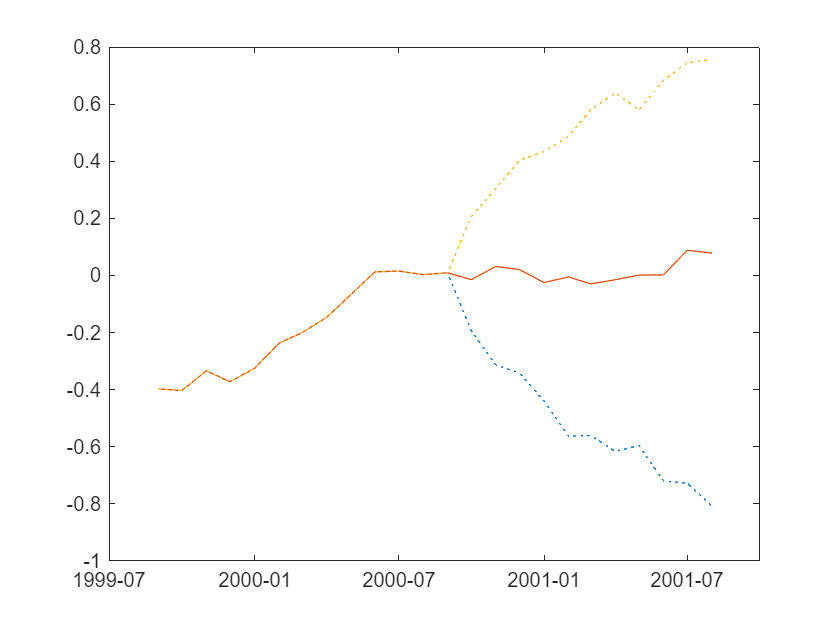


fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx);

tablex.plot( ...
    fcastPrctileTbx, "FYFF", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

## Identification


identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [117×1 double]
                 sigma: [3×3 double]
                    FY: [511×3 double]
                    LD: [120×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.7673    0.2879    0.0105
    0.2054    0.5201    0.0161
    0.3087    0.5661    1.1529
    0.0570    0.0340   -0.0031
    0.0078    0.0706   -0.0021
   -0.1198   -0.3817   -0.2216
    0.0071    0.0431   -0.0054
   -0.0342    0.0097   -0.0022
   -0.1793   -0.2622   -0.0079
    0.0038    0.0164   -0.0028


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.7673    0.2879    0.0105
    0.2054    0.5201    0.0161
    0.3087    0.5661    1.1529
    0.0570    0.0340   -0.0031
    0.0078    0.0706   -0.0021
   -0.1198   -0.3817   -0.2216
    0.0071    0.0431   -0.0054
   -0.0342    0.0097   -0.0022
   -0.1793   -0.2622   -0.0079
    0.0038    0.0164   -0.0028


## **Conditional forecast**

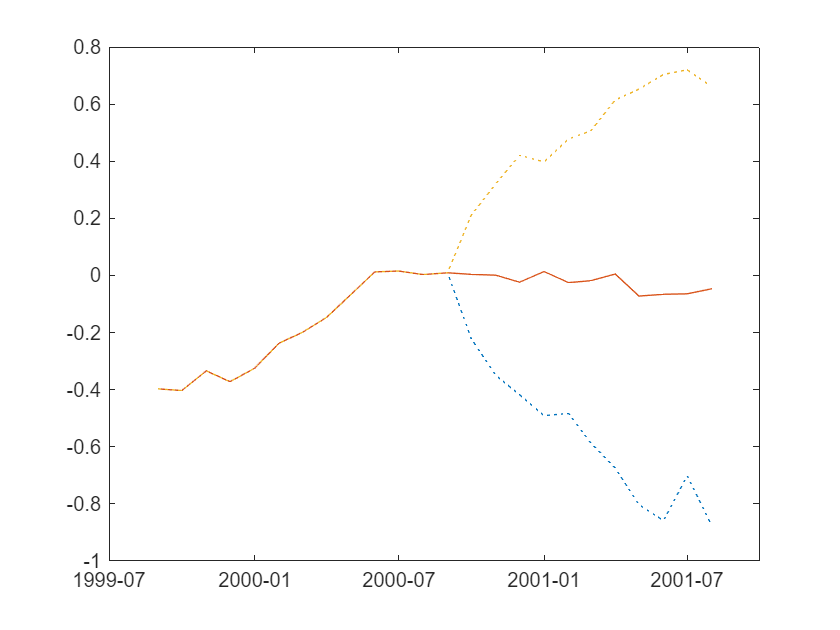


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

uncFcastPrctileTbx = tablex.apply(uncFcastTbl1, prctileFunc);
uncFcastPrctileTbx = tablex.flatten(uncFcastPrctileTbx);

tablex.plot( ...
    uncFcastPrctileTbx, "FYFF", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);



condDataTbl = tablex.fromFile(fullfile(tutpath,"condDataTblFAVAR.xlsx"));
planTbl = tablex.readConditioningPlan(fullfile(tutpath,"planTblFAVAR.xlsx"));


[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    fcastSpan, ...
    conditions=condDataTbl, ...
    plan=[] ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    fcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);
condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

cd(fullfile(tutpath))